clear
%%%%%%%%%%%
c_C = 0;  %ド　　 C
c_Cs= 1;  %ド＃　 C#
c_D = 2;  %レ　　 D
c_Ds= 3;  %レ＃　 D#
c_E = 4;  %ミ　　 E
c_F = 5;  %ファ　 F
c_Fs= 6;  %ファ＃ F#
c_G = 7;  %ソ　　 G
c_Gs= 8;  %ソ＃　 G#
c_A = 9;  %ラ　　 A
c_As=10;  %ラ＃　 A#
c_B =11;  %シ　　 B
rest=-1;
%%%%%%%%%%%

%各音符において生成する

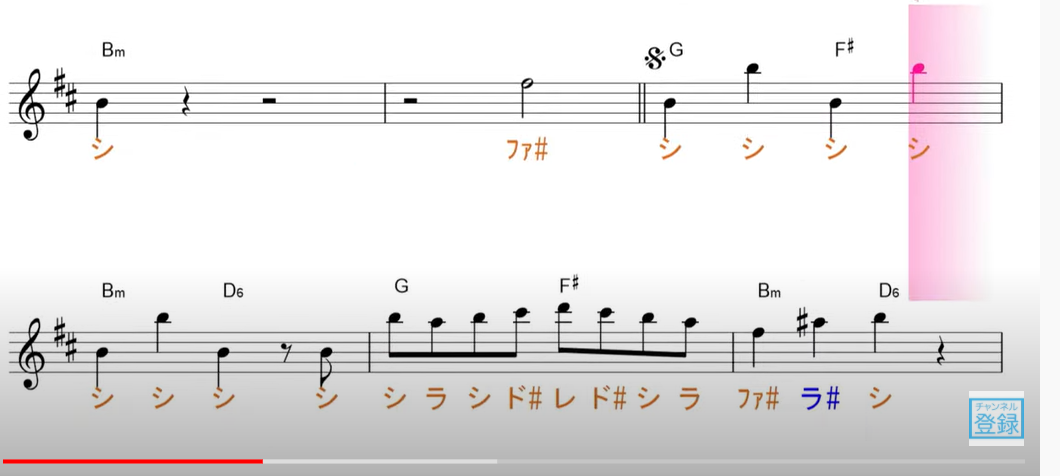


sym = 1;%note:1,rest:0
eta_c = c_C; %Cromatic scale note number
eta_o = 3; %octave number

N_bar = 4;%小節の数

N_sym1 = 4;%小節内の音(音符，休符)の数
N_sym2 = 5;%小節内の音(音符，休符)の数
N_sym3 = 8;%小節内の音(音符，休符)の数
N_sym4 = 5;%小節内の音(音符，休符)の数
BAR1(N_sym1,1) = zeros();
BAR2(N_sym2,1) = zeros();
BAR3(N_sym3,1) = zeros();
BAR4(N_sym4,1) = zeros();
BAR = cat(1,BAR1,BAR2,BAR3,BAR4);
N_sym = numel(BAR); %音の数

SYM_eta_c(N_sym,1) = zeros();%音のCromatic scale note number配列
eta_c1 = [c_B ,c_B ,c_B ,c_B ]';
eta_c2 = [c_B ,c_B ,c_B ,rest,c_B ]';
eta_c3 = [c_B ,c_A ,c_B ,c_Cs,c_D ,c_Cs,c_B ,c_A]';
eta_c4 = [c_Fs,rest,c_A ,c_B ,rest]';
SYM_eta_c = cat(1,eta_c1,eta_c2,eta_c3,eta_c4);

SYM_eta_o(N_sym,1) = zeros();%音のオクターブ配列
eta_o1 = [3,4,3,4]';
eta_o2 = [3,4,3,rest,4]';
eta_o3 = [4,4,4,4,4,4,4,4]';
eta_o4 = [4,rest,4,4,rest]';
SYM_eta_o = cat(1,eta_o1,eta_o2,eta_o3,eta_o4);

SYM_sym(N_sym,1) = zeros();%符号配列
for k = 1:1:N_sym    
   if SYM_eta_c(k,1) == rest
       SYM_sym(k,1) = 0;
   else       
       SYM_sym(k,1) = 1;
   end
end

SYM_f_H(N_sym,1) = zeros();%音の周波数配列
SYM_rot(N_sym,1) = zeros();%CW/CCW回転方向切替配列
n_rest = 0;%休符の数のカウント
for k = 1:1:N_sym
    %音の周波数配列
    SYM_f_H(k,1) = MusicFunction_f_H(SYM_sym(k,1),SYM_eta_c(k,1),SYM_eta_o(k,1));    
    
    %CW/CCW回転方向切替配列
    if SYM_f_H(k,1) == 0
        n_rest = 1 + n_rest;
    else
    end    
    if rem(k+n_rest,2) == 1     
        SYM_rot(k,1) = 1;    
    else
        SYM_rot(k,1) = 0; 
    end
end

SYM_eta_c

SYM_eta_c =     11
    11
    11
    11
    11
    11
    11
    -1
    11
    11


SYM_eta_o

SYM_eta_o =      3
     4
     3
     4
     3
     4
     3
    -1
     4
     4


SYM_f_H

SYM_f_H =   493.8833
  987.7666
  493.8833
  987.7666
  493.8833
  987.7666
  493.8833
         0
  987.7666
  987.7666


SYM_rot

SYM_rot =      1
     0
     1
     0
     1
     0
     1
     1
     0
     1



%%%%%%%%%%%%%%%%%%%%%
b_t = 4;  %beat :ビート [-]
f_t = 178;%tempo:テンポ [bpm]
SYM_d_note(N_sym,1) = zeros();%分割数配列
d_note1 = [4,4,4,4]';
d_note2 = [4,4,4,8,8]';
d_note3 = [8,8,8,8,8,8,8,8]';
d_note4 = [8,8,4,4,4]';
SYM_d_note = cat(1,d_note1,d_note2,d_note3,d_note4);

SYM_t_s(N_sym,1) =zeros();
for k = 1:1:N_sym
    %音の時間配列[s]
    %ｋ番目の音の時間
    SYM_t_s(k,1) = MusicFunction_t_s(b_t,f_t,SYM_d_note(k,1));
end
SYM_t_s

SYM_t_s =     0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.1685
    0.1685
    0.1685




%%%%%%%%%%%%%%%%%%%%%
f_L = 50;%起動周波数[Hz]
R_a = 10e-6;%加速レート[s/Hz]
R_d = 10e-6;%減速レート[s/Hz]

SYM_N(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音に必要なパルス数
    SYM_N(k,1) = MusicFunction_N(SYM_sym(k,1),SYM_t_s(k,1),SYM_f_H(k,1),f_L,R_a,R_d);
end
SYM_N

SYM_N =    164
   324
   164
   324
   164
   324
   164
     0
   157
   157



%%%%%%%%%%%%%%%%%%%%%
%判別式
%%もし三角駆動となった場合は，望む音を出すことが出来ない．
SYM_D_eq(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音に必要なパルス数
    SYM_D_eq(k,1) = function_D_eq(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1));
end


D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

休符

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

休符

D_eq > 0 となるため 台形駆動

休符

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

休符


SYM_D_eq

SYM_D_eq = 	1.0e+03 *

    3.5561
    4.7046
    3.5561
    4.7046
    3.5561
    4.7046
    3.5561
         0
    2.9749
    2.9749


%%%%%%%%%%%%%%%%%%%%%
SYM_t_H(N_sym,1) =zeros();
SYM_t_max(N_sym,1) =zeros();
SYM_t_a(N_sym,1) =zeros();
SYM_t_b(N_sym,1) =zeros();
SYM_t_c(N_sym,1) =zeros();
SYM_t_sum(N_sym,1) =zeros();
SYM_N_a(N_sym,1) =zeros();
SYM_N_b(N_sym,1) =zeros();
SYM_N_c(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音の各種情報
    [SYM_t_H(k,1),...
        SYM_t_max(k,1),...
        SYM_t_a(k,1),...
        SYM_t_b(k,1),...
        SYM_t_c(k,1),...
        SYM_t_sum(k,1),...
        SYM_N_a(k,1),...
        SYM_N_b(k,1),...
        SYM_N_c(k,1)] = ...
        function_drive_info(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1));
    if SYM_sym(k,1) == 0
        SYM_t_b(k,1) = SYM_t_s(k,1);
        SYM_t_sum(k,1) = SYM_t_s(k,1);
    end
end

仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.0088777 [s]
Nを無視し，三角駆動した場合の総時間 =0.08 [s]
加速に必要な時間 =0.0044388 [s]
等速に必要な時間 =0.32801 [s]
減速に必要な時間 =0.0044388 [s]
台形駆動にかかる時間 =0.33689 [s]
加速に必要なパルス数 =1 [-]
等速に必要なパルス数 =162 [-]
減速に必要なパルス数 =1 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.018755 [s]
Nを無視し，三角駆動した場合の総時間 =0.11285 [s]
加速に必要な時間 =0.0093777 [s]
等速に必要な時間 =0.31789 [s]
減速に必要な時間 =0.0093777 [s]
台形駆動にかかる時間 =0.33664 [s]
加速に必要なパルス数 =5 [-]
等速に必要なパルス数 =314 [-]
減速に必要なパルス数 =5 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.0088777 [s]
Nを無視し，三角駆動した場合の総時間 =0.08 [s]
加速に必要な時間 =0.0044388 [s]
等速に必要な時間 =0.32801 [s]
減速に必要な時間 =0.0044388 [s]
台形駆動にかかる時間 =0.33689 [s]
加速に必要なパルス数 =1 [-]
等速に必要なパルス数 =162 [-]
減速に必要なパルス数 =1 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.018755 [s]
Nを無視し，三角駆動した場合の総時間 =0.11285 [s]
加速に必要な時間 =0.0093777 [s]
等速に必要な時間 =0.31789 [s]
減速に必要な時間 =0.0093777 [s]
台形駆動にかかる時間 =0.33664 [s]
加速に必要なパルス数 =5 [-]
等速に必要なパルス数 =314 [-]
減速に必要なパルス数 =5 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.0088777 [s]
Nを無視し，三角駆動した場合の総時間 =0.08 [s]
加速に必要な時間 =0.0044


% SYM_t_H
% SYM_t_max
% SYM_t_a
SYM_t_b

SYM_t_b =     0.3280
    0.3179
    0.3280
    0.3179
    0.3280
    0.3179
    0.3280
    0.1685
    0.1488
    0.1488


% SYM_t_c
SYM_t_sum

SYM_t_sum =     0.3369
    0.3366
    0.3369
    0.3366
    0.3369
    0.3366
    0.3369
    0.1685
    0.1676
    0.1676


% SYM_N_a
% SYM_N_b
% SYM_N_c
% 

%%%%%%%%%%%%%%%%%%%%%%
theta_s_deg = 0.72;
%理想的な励磁タイミング行列を作成

%k列目がk番目の音価の理想的な励磁タイミング配列となっている
T_M(max(SYM_N),N_sym)=zeros();
THETA_r_deg(max(SYM_N),N_sym) = zeros();
    for k = 1:1:N_sym
        if SYM_N(k,1) ~= 0%休符の時のT_Mを飛ばすためのfor文
            [T_M(1:SYM_N(k,1),k),THETA_r_deg(1:SYM_N(k,1),k)]=...
            function_T_M(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1),theta_s_deg);        
        else            
        end
    end


D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動

T_M

T_M =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040         0    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040         0    0.0040         0    0.0040    0.0040         0
    0.0060    0.0058    0.0060    0.0058    0.0060    0.0058    0.0060         0    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058         0    0.0058         0    0.0058    0.0058         0
    0.0080    0.0073    0.0080    0.0073    0.0080    0.0073    0.0080         0    0.0073    0.0073    0.0073    0.0073    0.0076    0.0075    0.0076    0.0073    0.0073         0    0.0073         0    0.0073    0.0073         0
    0.0101    0.0085    0.0101    0.0085    0.0101    0.0085    0.0101         0    0.0085    0.0085    0.0085    0.0085    0.0095    0.0092    0.0095    0.0085    0.0085         0    0.0086         0    0.0085    0.0085         0
    0.0121    0.0095    0.0121    0.0095    0.0121    0.0095    0.0121

    
%%%%%
%パルスを生成
T_s = 50e-5;
SYM_nu(N_sym,1) = zeros();%k番目の符号に必要なnu
    for k = 1:1:N_sym
        SYM_nu(k,1) = round(SYM_t_sum(k,1)/T_s);%一応任意に選ぶことが可能．
    end
V_pp = 1;
V_pm = 0;

P_M(max(SYM_nu),N_sym)=zeros();%ｋ列目はｋ番目の音を生成するための台形駆動パルスが格納
    for k = 1:1:N_sym
        if SYM_N(k,1) ~= 0%音符の時
            P_M(1:SYM_nu(k,1),k) = function_P_M(T_s,SYM_t_sum(k,1),T_M(1:SYM_N(k,1),k),V_pp,V_pm)
        else   %休符の時
            P_M(1:SYM_nu(k,1),k) = zeros();
        end
    end

励磁パルス配列PMの配列数 = 674 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0   

励磁パルス配列PMの配列数 = 673 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0   

励磁パルス配列PMの配列数 = 674 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 673 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 674 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 673 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 674 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 335 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 335 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 335 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 335 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 334 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 338 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 334 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 335 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 167 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 338 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 674 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

励磁パルス配列PMの配列数 = 673 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

P_M    

P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   

%%%%%%%%%%%%%%%%%%%%
%実際に励磁するパルスpulseと，CW/CCW切替用の配列の2つのFrom Workspace用配列を作成する
sum_nu = 0;
for m = 1 : 1 :N_sym
    sum_nu = SYM_nu(m,1) + sum_nu;
end

MusicPulse(sum_nu,2) = zeros();
DoR(sum_nu,2) = zeros();%Direction of rotation

    for m = 1 : 1 :sum_nu
        MusicPulse(m,1) = T_s*m;
        DoR(m,1) = T_s*m;
    end
    MP = P_M(1:SYM_nu(1,1),1);
    for k = 2:1:N_sym
        MP = cat(1,MP,P_M(1:SYM_nu(k,1),k))
    end

MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


MP =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


    MusicPulse(1:sum_nu,2) = MP;
    
    rot_num(max(SYM_nu),N_sym) = zeros();
    for k = 1:1:N_sym
        for l = 1:1:SYM_nu(k,1)
            rot_num(l,k) = SYM_rot(k,1);
        end
    end
    dor = rot_num(1:SYM_nu(1,1),1);
    for k = 2:1:N_sym
        dor = cat(1,dor,rot_num(1:SYM_nu(k,1),k));
    end
    DoR(1:sum_nu,2) = dor;
    
%Triggered Signal From Workspaeを使用するために、行ベクトルに変換。最初からこっちでいいかも知れない。
%
MusicPulseRow(1,sum_nu) = zeros();
 for m = 1 : 1 : sum_nu
     MusicPulseRow(1,m) = MusicPulse(m,2); 
%      pulse_row_ave(1,m) = pulse_ave01(m,2); 
 end
clearvars MusicPulse
MusicPulse(1,sum_nu) = zeros();
MusicPulse =MusicPulseRow

MusicPulse =      0     0     0     0     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     1     0     0



DoRRow(1,sum_nu) = zeros();
 for m = 1 : 1 : sum_nu
     DoRRow(1,m) = DoR(m,2); 
%      pulse_row_ave(1,m) = pulse_ave01(m,2); 
 end
clearvars DoR
DoR(1,sum_nu) = zeros();
DoR =DoRRow

DoR =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


%%%%%%%%%%%%%%
t_sim = 6.0;%外部PCで回転速度を計測する時間   
